# Interpolation

## Structure data

clear all; clc; addpath('./functions/')
load('./data/dc_corr.mat'); 

Compute the density in the surface (bird/m^3 -> bird/km^2) and the score of the time in the night (-1 sunset to 1 sunrise)

for i_d=1:numel(dc)
  weight=diff(double([0 max(0, (1:dc(i_d).levels).*dc(i_d).interval - dc(i_d).height )]))/1;
  dc(i_d).denss = dc(i_d).dens*weight';
  dc(i_d).scoret = datenum(dc(i_d).time'-mean([dc(i_d).sunrise;dc(i_d).sunset])) ./ datenum(dc(i_d).sunrise-dc(i_d).sunset)*2;
end

Define the threshold of density to take into account

dens_lim = 0;

Structure the data as a table

data=[];
for i_d=1:numel(dc)
  id = dc(i_d).scoret(:)>=-1 & dc(i_d).scoret(:)<=1 & dc(i_d).denss>dens_lim;
  d=table();
  d.dens=dc(i_d).denss(id);
  d.dens_pred=ones(sum(id),1);
  d.i_d=i_d*ones(sum(id),1);
  d.lat=dc(i_d).lat*ones(sum(id),1);
  d.lon=dc(i_d).lon*ones(sum(id),1);
  d.time = datenum(dc(i_d).time(id));
  data = [data ; d ];
end


## Estimation

Define the threshold of the radar to eliminate in the estimation. Only radar more distant will be used in the interpolation

distlelim = 0; % km

Define the ratio distance/time for the interpolation (eg. 1 day = 1degree lat/lon). This value as been optimized with the data (see section below).

ratio_coord_time= 13;

Estimation

D = squareform(pdist([[dc.lat]' [dc.lon]'],@lldistkm));
for i_d=1:numel(dc)
  
  id1=find(D(i_d,:)>distlelim);
  id2=ismember(data.i_d,id1);
  id3=data.i_d==i_d;
  
  F = scatteredInterpolant(data.lat(id2),data.lon(id2),data.time(id2).*ratio_coord_time,data.dens(id2),'natural');
  data.dens_pred(id3) = F(data.lat(id3),data.lon(id3),data.time(id3).*ratio_coord_time);
  
  % data.dens_pred(id3) = griddata(data.lat(id2),data.lon(id2),data.time(id2).*ratio_coord_time,data.dens(id2),data.lat(id3),data.lon(id3),data.time(id3).*ratio_coord_time)
end

## Figure

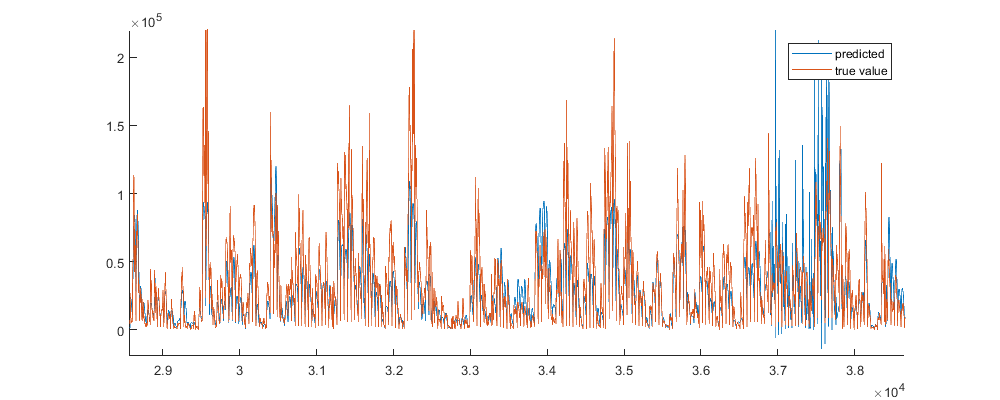

figure('position',[0 0 1000 400]); hold on; plot(data.dens_pred); plot(data.dens); axis tight; legend('predicted','true value')

RMSE

sqrt(mean((data.dens_pred-data.dens).^2))

ans = 1.8474e+04

Save

save('data/Density_Interpol.mat','data')

Comparing to Model

% load('data/Density_Interpol.mat','data')

## Calibrate` ratio_coord_time`

ratio_coord_time =    1000 *[ 0.0184    0.1006   -0.0024   -0.0007   -0.0013    0.0154    0.5188    0.0236    0.3456    0.0125    0.1205    0.1871    0.0738    0.1084    0.0266    0.0090    0.0036    0.6481   -0.0017    0.0131    0.3464 0.0130    0.9928    0.0130    0.0899    0.0130    0.0130    0.2673    0.0181    0.0202    2.4713    0.0571    0.5818    0.5503    0.0130    0.1414    0.0839    0.0040    0.1486    0.0179    0.0130    0.0130 0.4111    0.0040    0.0130    0.0130    0.1771   -0.0013    0.1080    0.0108    0.0235    0.0130    0.0074    0.0148    0.0332   -0.0013    0.0130   -0.0013    0.0091    0.0039   -0.0013    0.0388    0.0130 -0.0013    0.0104    0.0052    0.0039   -0.0013    0.0123];

parfor i_d=1:numel(dc)
  id1=find(D(i_d,:)>distlelim);
  id2=ismember(data.i_d,id1);
  id3=data.i_d==i_d;
  
  interpolafx =@(x) griddata(data.lat(id2),data.lon(id2),data.time(id2).*x,data.dens(id2),data.lat(id3),data.lon(id3),data.time(id3).*x,'natural');
  rmse = @(x) nansum( (interpolafx(x)-data.dens(id3)).^2 );
  
  % options = optimset('PlotFcns',{@optimplotfval,@optimplotx},'MaxFunEvals',100);
  options = optimset('MaxFunEvals',30);
  ratio_coord_time(i_d) = fminsearch(rmse,ratio_coord_time(i_d),options)
  % ratio_coord_time = fminbnd(rmse,0,1,options);
end

Figure


figure; histogram(ratio_coord_time(ratio_coord_time>0 & ratio_coord_time<100),100); xlabel('ratio_coord_time');

data_interp = load('data/Density_Interpol.mat','data');

figure('position',[0 0 400 400]); hold on;
scatter(data.dens_est,data.dens,'.k')
scatter(data_interp.data.dens_pred,data.dens,'.g')
plot([0 max(data.dens)],[0 max(data.dens)],'-r','LineWidth',2);
axis equal;xlabel('Estimate value'); ylabel('True value');